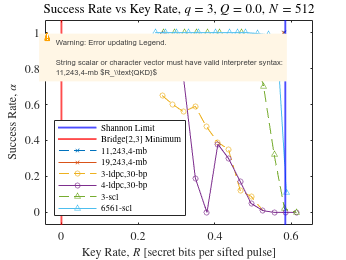

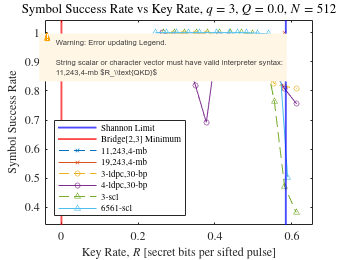

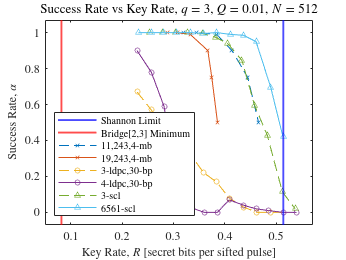

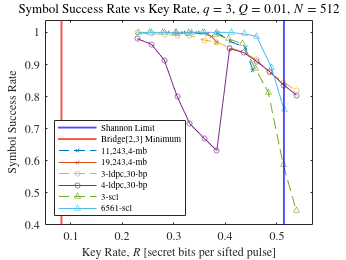

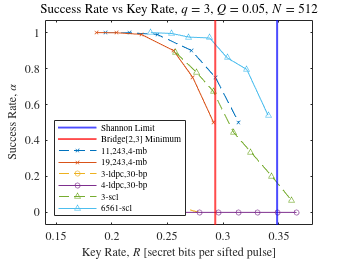

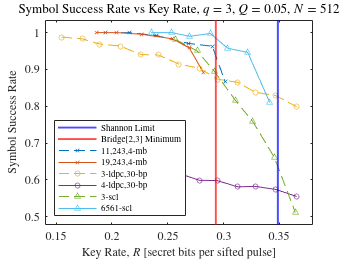

% All protocols
% Success rate vs Key rate for q=3, Q=[0.0,0.01,0.05], N=512
relations = ["success_rate_vs_key_rate", "symbol_success_rate_vs_key_rate"];

show_title = true;
y_logscale = false;
agg = false;
show_sd = false;
show_legend = true;
save = true;
custom_file_name = 'all_protocols';

q = 3;
p_err_str_list = ["0.0", "0.01", "0.05"];
N = 512;
min_key_rate = 0.25;
relative_gap_rate = [];

% MB data
block_length = [11, 19];
list_size = [243];
max_num_indices_to_encode = [4];

% LDPC data
sparsity = [3, 4];
max_num_rounds = [];

% Polar data
scl_l = [3, 6561];

for p_err_str = p_err_str_list
    A_mb = get_data('mb', q, p_err_str, agg, 'full_reduce', N, min_key_rate);
    A_mb = filter_mb(A_mb, block_length, list_size, max_num_indices_to_encode, []);
    A_ldpc = get_data('ldpc', q, p_err_str, agg, 'full_reduce', N, min_key_rate);
    A_ldpc = filter_ldpc(A_ldpc, sparsity, max_num_rounds, [], relative_gap_rate, []);
    A_polar = get_data('polar', q, p_err_str, agg, 'full_reduce', N, min_key_rate);
    A_polar = filter_polar(A_polar, scl_l, [], relative_gap_rate);
    A = union(A_mb, A_ldpc);
    A = union(A, A_polar);
    for relation = relations
        plot_ir(A, relation, show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
    end
end

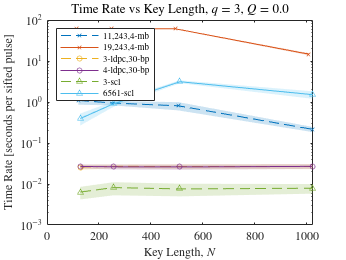

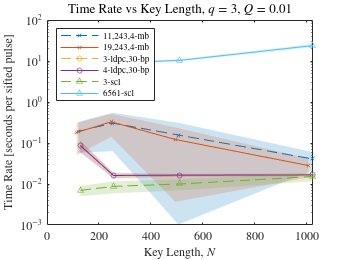

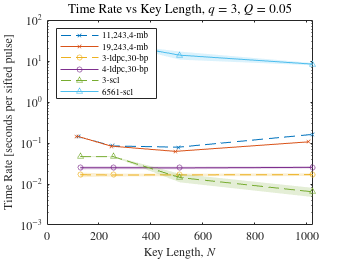

% All protocols
% Time rate vs N for q=3, Q=[0.0,0.01,0.05], relative rate 0.8
show_title = true;
y_logscale = true;
agg = false;
show_sd = true;
show_legend = true;
save = true;
custom_file_name = 'all_protocols';

q = 3;
p_err_str_list = ["0.0", "0.01", "0.05"];
N = [];
min_key_rate = [];
relative_gap_rate = [0.8];

% MB data
block_length = [11, 19];
list_size = [243];
max_num_indices_to_encode = [4];

% LDPC data
sparsity = [3, 4];
max_num_rounds = [];

% Polar data
scl_l = [3, 6561];

for p_err_str = p_err_str_list
    A_mb = get_data('mb', q, p_err_str, agg, 'full_reduce', N, min_key_rate);
    A_mb = filter_mb(A_mb, block_length, list_size, max_num_indices_to_encode, []);
    A_ldpc = get_data('ldpc', q, p_err_str, agg, 'full_reduce', N, min_key_rate);
    A_ldpc = filter_ldpc(A_ldpc, sparsity, max_num_rounds, [], relative_gap_rate, []);
    A_polar = get_data('polar', q, p_err_str, agg, 'full_reduce', N, min_key_rate);
    A_polar = filter_polar(A_polar, scl_l, [], relative_gap_rate);
    A = union(A_mb, A_ldpc);
    A = union(A, A_polar);
    plot_ir(A, 'time_rate_vs_N', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
    % plot_ir(A, 'cpu_time_rate_vs_N', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
end

% ------------------

ans = 1×71 table
    q     N     p_err    qer     use_log     list_size    check_length    theoretic_key_rate    code_strategy    mb_desired_success_rate    mb_block_length    mb_num_blocks    mb_full_rank_encoding    mb_use_zeroes_in_encoding_matrix    mb_indices_to_encode_strategy    mb_rounding_strategy    mb_pruning_strategy     mb_max_num_indices_to_encode    mb_max_candidates_num    mb_encoding_sample_size    mb_radius_picking    mb_predetermined_number_of_encodings    ldpc_sparsity    ldpc_syndrome_length    ldpc_desired_key_rate    ldpc_desired_syndrome

ans = 1×71 table
    q     N      p_err    qer    use_log     list_size    check_length    theoretic_key_rate    code_strategy    mb_desired_success_rate    mb_block_length    mb_num_blocks    mb_full_rank_encoding    mb_use_zeroes_in_encoding_matrix    mb_indices_to_encode_strategy    mb_rounding_strategy    mb_pruning_strategy     mb_max_num_indices_to_encode    mb_max_candidates_num    mb_encoding_sample_size    mb_radius_picking    mb_predetermined_number_of_encodings    ldpc_sparsity    ldpc_syndrome_length    ldpc_desired_key_rate    ldpc_desired_syndrome

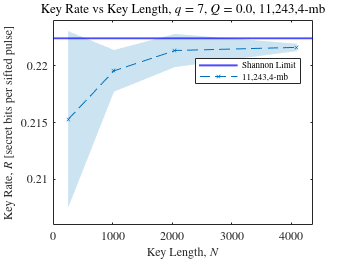

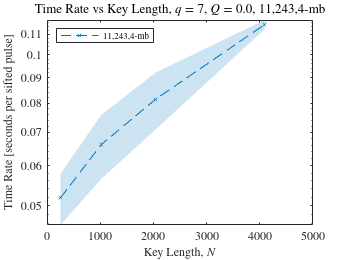

ans = 1×71 table
    q     N     p_err    qer     use_log     list_size    check_length    theoretic_key_rate    code_strategy    mb_desired_success_rate    mb_block_length    mb_num_blocks    mb_full_rank_encoding    mb_use_zeroes_in_encoding_matrix    mb_indices_to_encode_strategy    mb_rounding_strategy    mb_pruning_strategy     mb_max_num_indices_to_encode    mb_max_candidates_num    mb_encoding_sample_size    mb_radius_picking    mb_predetermined_number_of_encodings    ldpc_sparsity    ldpc_syndrome_length    ldpc_desired_key_rate    ldpc_desired_syndrome

ans = 1×71 table
    q     N      p_err    qer    use_log     list_size    check_length    theoretic_key_rate    code_strategy    mb_desired_success_rate    mb_block_length    mb_num_blocks    mb_full_rank_encoding    mb_use_zeroes_in_encoding_matrix    mb_indices_to_encode_strategy    mb_rounding_strategy    mb_pruning_strategy     mb_max_num_indices_to_encode    mb_max_candidates_num    mb_encoding_sample_size    mb_radius_picking    mb_predetermined_number_of_encodings    ldpc_sparsity    ldpc_syndrome_length    ldpc_desired_key_rate    ldpc_desired_syndrome

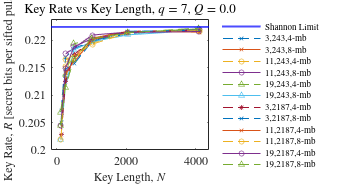

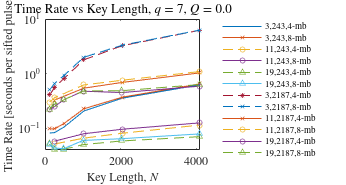

ans = 1×71 table
    q     N     p_err    qer     use_log     list_size    check_length    theoretic_key_rate    code_strategy    mb_desired_success_rate    mb_block_length    mb_num_blocks    mb_full_rank_encoding    mb_use_zeroes_in_encoding_matrix    mb_indices_to_encode_strategy    mb_rounding_strategy    mb_pruning_strategy     mb_max_num_indices_to_encode    mb_max_candidates_num    mb_encoding_sample_size    mb_radius_picking    mb_predetermined_number_of_encodings    ldpc_sparsity    ldpc_syndrome_length    ldpc_desired_key_rate    ldpc_desired_syndrome

ans = 1×71 table
    q     N      p_err    qer     use_log     list_size    check_length    theoretic_key_rate    code_strategy    mb_desired_success_rate    mb_block_length    mb_num_blocks    mb_full_rank_encoding    mb_use_zeroes_in_encoding_matrix    mb_indices_to_encode_strategy    mb_rounding_strategy    mb_pruning_strategy     mb_max_num_indices_to_encode    mb_max_candidates_num    mb_encoding_sample_size    mb_radius_picking    mb_predetermined_number_of_encodings    ldpc_sparsity    ldpc_syndrome_length    ldpc_desired_key_rate    ldpc_desired_syndrom

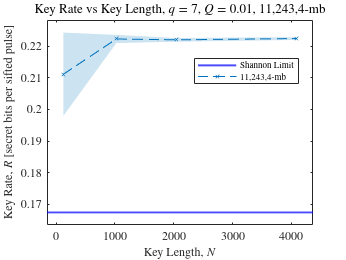

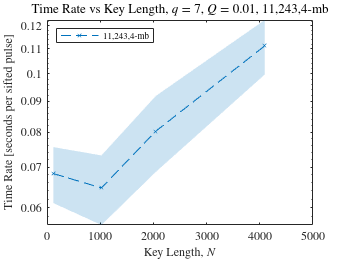

ans = 1×71 table
    q     N     p_err    qer     use_log     list_size    check_length    theoretic_key_rate    code_strategy    mb_desired_success_rate    mb_block_length    mb_num_blocks    mb_full_rank_encoding    mb_use_zeroes_in_encoding_matrix    mb_indices_to_encode_strategy    mb_rounding_strategy    mb_pruning_strategy     mb_max_num_indices_to_encode    mb_max_candidates_num    mb_encoding_sample_size    mb_radius_picking    mb_predetermined_number_of_encodings    ldpc_sparsity    ldpc_syndrome_length    ldpc_desired_key_rate    ldpc_desired_syndrome

ans = 1×71 table
    q     N      p_err    qer     use_log     list_size    check_length    theoretic_key_rate    code_strategy    mb_desired_success_rate    mb_block_length    mb_num_blocks    mb_full_rank_encoding    mb_use_zeroes_in_encoding_matrix    mb_indices_to_encode_strategy    mb_rounding_strategy    mb_pruning_strategy     mb_max_num_indices_to_encode    mb_max_candidates_num    mb_encoding_sample_size    mb_radius_picking    mb_predetermined_number_of_encodings    ldpc_sparsity    ldpc_syndrome_length    ldpc_desired_key_rate    ldpc_desired_syndrom

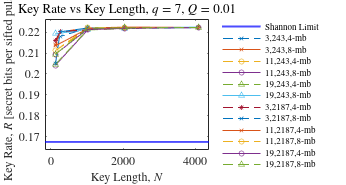

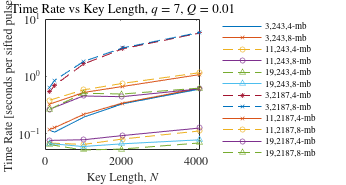

ans = 1×71 table
    q     N     p_err    qer     use_log     list_size    check_length    theoretic_key_rate    code_strategy    mb_desired_success_rate    mb_block_length    mb_num_blocks    mb_full_rank_encoding    mb_use_zeroes_in_encoding_matrix    mb_indices_to_encode_strategy    mb_rounding_strategy    mb_pruning_strategy     mb_max_num_indices_to_encode    mb_max_candidates_num    mb_encoding_sample_size    mb_radius_picking    mb_predetermined_number_of_encodings    ldpc_sparsity    ldpc_syndrome_length    ldpc_desired_key_rate    ldpc_desired_syndrome

ans = 1×71 table
    q     N      p_err    qer     use_log     list_size    check_length    theoretic_key_rate    code_strategy    mb_desired_success_rate    mb_block_length    mb_num_blocks    mb_full_rank_encoding    mb_use_zeroes_in_encoding_matrix    mb_indices_to_encode_strategy    mb_rounding_strategy    mb_pruning_strategy     mb_max_num_indices_to_encode    mb_max_candidates_num    mb_encoding_sample_size    mb_radius_picking    mb_predetermined_number_of_encodings    ldpc_sparsity    ldpc_syndrome_length    ldpc_desired_key_rate    ldpc_desired_syndrom

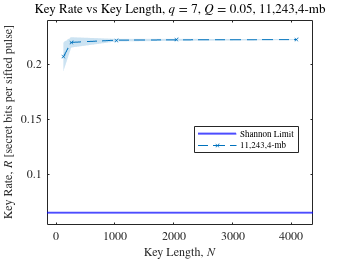

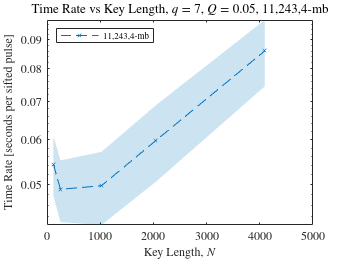

ans = 1×71 table
    q     N     p_err    qer     use_log     list_size    check_length    theoretic_key_rate    code_strategy    mb_desired_success_rate    mb_block_length    mb_num_blocks    mb_full_rank_encoding    mb_use_zeroes_in_encoding_matrix    mb_indices_to_encode_strategy    mb_rounding_strategy    mb_pruning_strategy     mb_max_num_indices_to_encode    mb_max_candidates_num    mb_encoding_sample_size    mb_radius_picking    mb_predetermined_number_of_encodings    ldpc_sparsity    ldpc_syndrome_length    ldpc_desired_key_rate    ldpc_desired_syndrome

ans = 1×71 table
    q     N      p_err    qer     use_log     list_size    check_length    theoretic_key_rate    code_strategy    mb_desired_success_rate    mb_block_length    mb_num_blocks    mb_full_rank_encoding    mb_use_zeroes_in_encoding_matrix    mb_indices_to_encode_strategy    mb_rounding_strategy    mb_pruning_strategy     mb_max_num_indices_to_encode    mb_max_candidates_num    mb_encoding_sample_size    mb_radius_picking    mb_predetermined_number_of_encodings    ldpc_sparsity    ldpc_syndrome_length    ldpc_desired_key_rate    ldpc_desired_syndrom

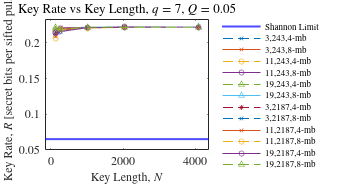

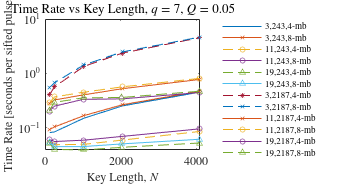

% MB:
% Key rate vs N for q=3, Q=[0.0,0.01,0.05], success_rate = 0.999
% Time rate vs N for q=3, Q=[0.0,0.01,0.05], success_rate = 0.999
show_title = true;
agg = false;
show_legend = true;
save = true;

q_list = [3, 5, 7];
N = [];
min_key_rate = [];
p_err_str_list = ["0.0", "0.01", "0.05"];
success_rate_str_list = ["0.999"];

code_strategy = 'mb';

for q = q_list
    for p_err_str = p_err_str_list
        if strcmp(p_err_str, "0.0")
            cur_success_rate_str_list = ["1.0"];
        else
            cur_success_rate_str_list = success_rate_str_list;
        end
        for success_rate_str = cur_success_rate_str_list
            custom_file_name = 'mb-single';
            show_sd = true;
            block_length = [11];
            list_size = [243];
            max_num_indices_to_encode = [4];
            A = get_data(code_strategy, q, p_err_str, agg, 'full_reduce', N, min_key_rate);
            A = filter_mb(A, block_length, list_size, max_num_indices_to_encode, success_rate_str);
            plot_ir(A, 'key_rate_vs_N', show_title, false, show_sd, show_legend, save, custom_file_name);
            plot_ir(A, 'time_rate_vs_N', show_title, true, show_sd, show_legend, save, custom_file_name);
            % plot_ir(A, 'cpu_time_rate_vs_N', show_title, true, show_sd, show_legend, save, custom_file_name);
    
            custom_file_name = 'mb-batch';
            show_sd = false;
            block_length = [3, 11, 19];
            list_size = [243, 2187];
            max_num_indices_to_encode = [4, 8];
            A = get_data(code_strategy, q, p_err_str, agg, 'full_reduce', N, min_key_rate);
            A = filter_mb(A, block_length, list_size, max_num_indices_to_encode, success_rate_str);
            plot_ir(A, 'key_rate_vs_N', show_title, false, show_sd, show_legend, save, custom_file_name);
            plot_ir(A, 'time_rate_vs_N', show_title, true, show_sd, show_legend, save, custom_file_name);
            % plot_ir(A, 'cpu_time_rate_vs_N', show_title, true, show_sd, show_legend, save, custom_file_name);
        end
    end
end

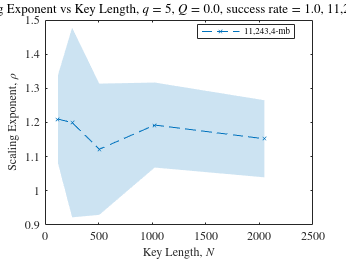

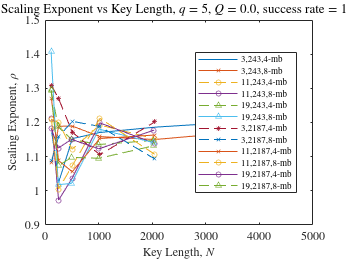

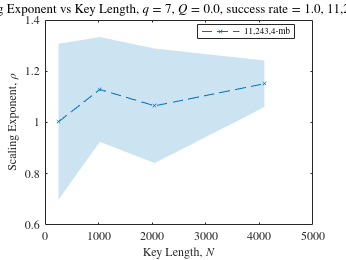

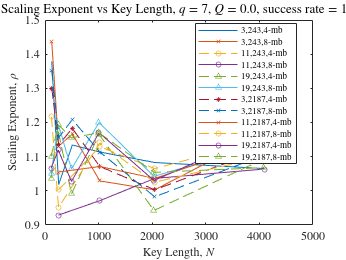

% MB:
% Scalexp vs N for q=3, Q=0.0, success_rate = 1.0
show_title = true;
y_logscale = false;
agg = false;
show_legend = true;
save = true;

q_list = [3, 5, 7];
N = [];
min_key_rate = [];
p_err_str = "0.0";
success_rate_str = "1.0";

code_strategy = 'mb';

for q = q_list
    custom_file_name = 'mb-single';
    show_sd = true;
    block_length = [11];
    list_size = [243];
    max_num_indices_to_encode = [4];
    A = get_data(code_strategy, q, p_err_str, agg, 'full_reduce', N, min_key_rate);
    A = filter_mb(A, block_length, list_size, max_num_indices_to_encode, success_rate_str);
    plot_ir(A, 'scalexp_vs_N', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
    
    custom_file_name = 'mb-batch';
    show_sd = false;
    block_length = [3, 11, 19];
    list_size = [243, 2187];
    max_num_indices_to_encode = [4, 8];
    A = get_data(code_strategy, q, p_err_str, agg, 'full_reduce', N, min_key_rate);
    A = filter_mb(A, block_length, list_size, max_num_indices_to_encode, success_rate_str);
    plot_ir(A, 'scalexp_vs_N', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
end

% ------------------

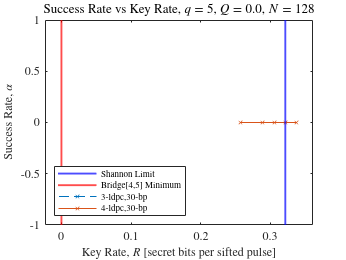

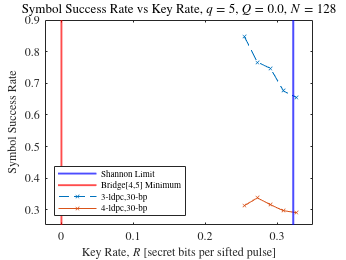

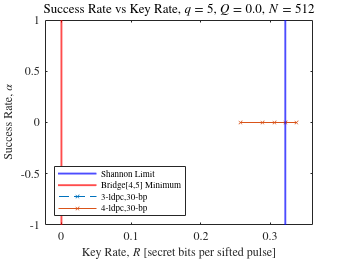

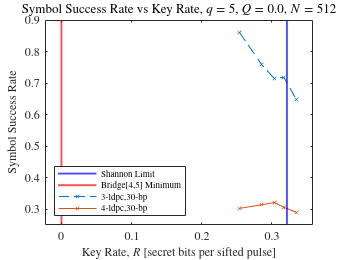

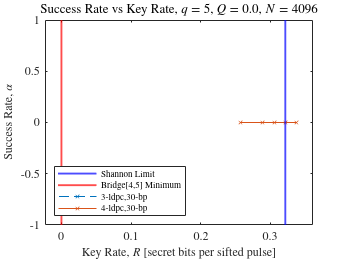

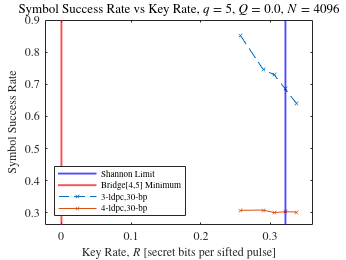

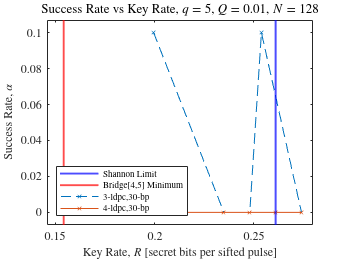

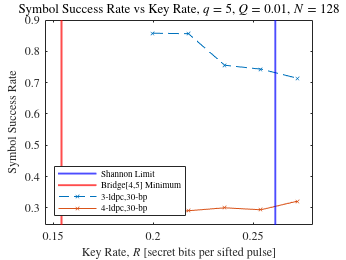

% LDPC:
% Success rate vs Key rate for q=3, Q=[0.0,0.01,0.05], N=[128, 512, 4096]
show_title = true;
y_logscale = false;
agg = false;
show_sd = false;
show_legend = true;
save = true;
custom_file_name = 'ldpc-single';

code_strategy = 'ldpc';
result_type = 'full_reduce';
q_list = [3, 5];
p_err_str_list = ["0.0", "0.01", "0.05"];
N_list = [128, 512, 4096];
sparsity = [3, 4];
max_num_rounds = [];

for q = q_list
    for p_err_str = p_err_str_list
        for N = N_list
            A = get_data(code_strategy, q, p_err_str, agg, result_type, N, []);
            A = filter_ldpc(A, sparsity, max_num_rounds, [], [], []);
            plot_ir(A, 'success_rate_vs_key_rate', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
            plot_ir(A, 'symbol_success_rate_vs_key_rate', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
        end
    end
end

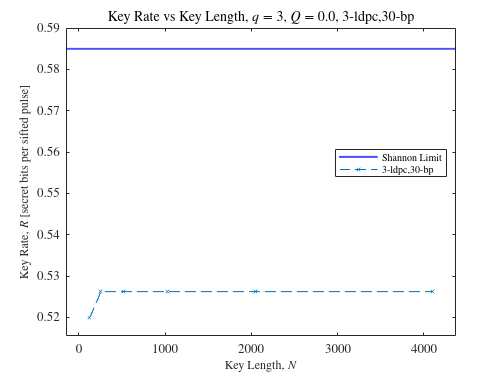

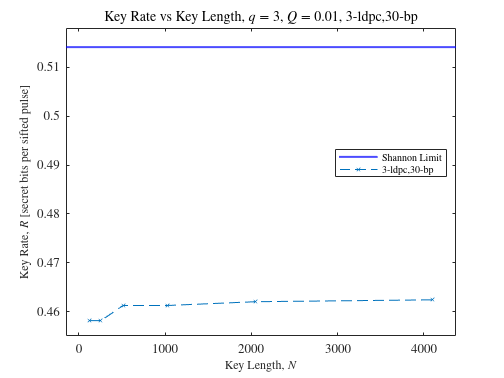

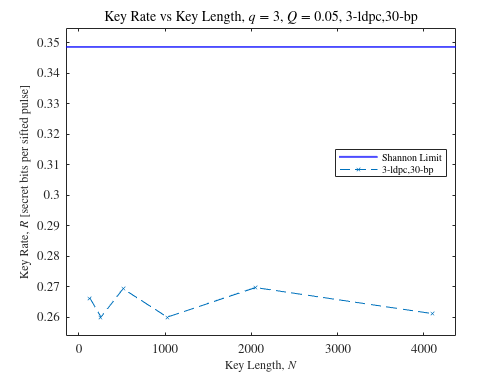

% LDPC:
% Key rate vs N for q=3, Q=[0.0,0.01,0.05], ssr = 0.9
show_title = true;
y_logscale = false;
agg = false;
show_sd = false;
show_legend = true;
save = true;
custom_file_name = 'ldpc-single';

code_strategy = 'ldpc';
result_type = 'full_reduce';
q = 3;
p_err_str_list = ["0.0", "0.01", "0.05"];
sparsity = [3];
max_num_rounds = [];
ssr = 0.9;

for p_err_str = p_err_str_list
    A = get_data(code_strategy, q, p_err_str, agg, result_type, [], []);
    A = filter_ldpc(A, sparsity, max_num_rounds, [], [], ssr);
    plot_ir(A, 'key_rate_vs_N', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
end

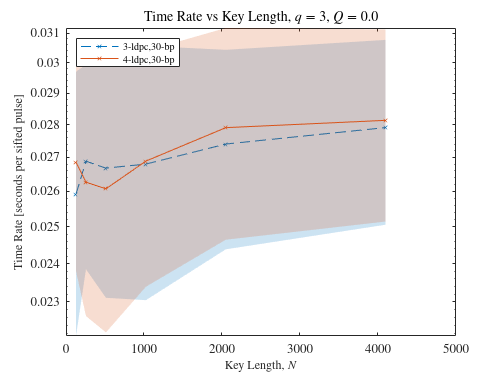

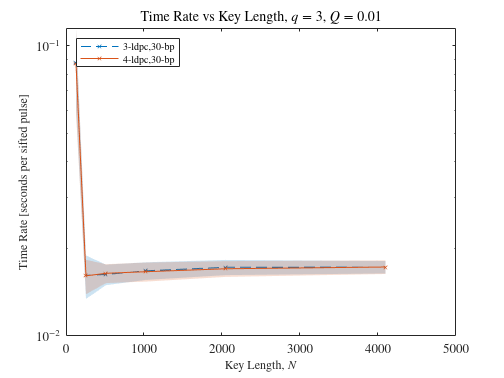

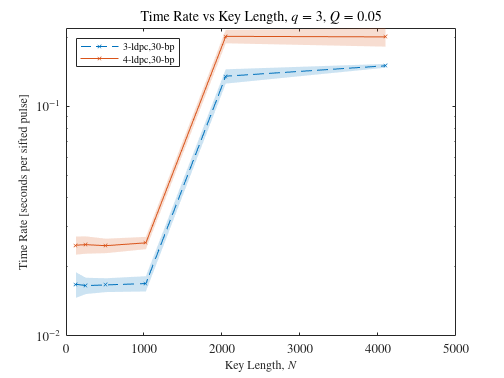

% LDPC:
% Time rate vs N for q=3, Q=[0.0,0.01,0.05], relative rate 0.8
show_title = true;
y_logscale = true;
agg = false;
show_sd = true;
show_legend = true;
save = true;
custom_file_name = 'ldpc-single';

code_strategy = 'ldpc';
result_type = 'full_reduce';
q = 3;
p_err_str_list = ["0.0", "0.01", "0.05"];
sparsity = [3, 4];
max_num_rounds = [];
relative_gap_rate = 0.8;
ssr = [];

for p_err_str = p_err_str_list
    A = get_data(code_strategy, q, p_err_str, agg, result_type, [], []);
    A = filter_ldpc(A, sparsity, max_num_rounds, [], relative_gap_rate, ssr);
    plot_ir(A, 'time_rate_vs_N', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
    % plot_ir(A, 'cpu_time_rate_vs_N', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
end

% ------------------

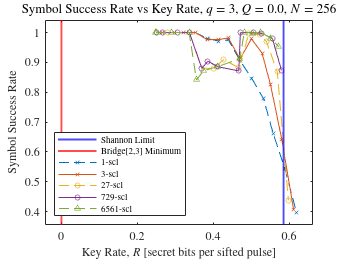

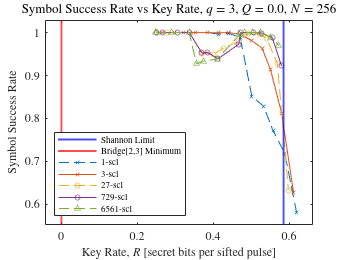

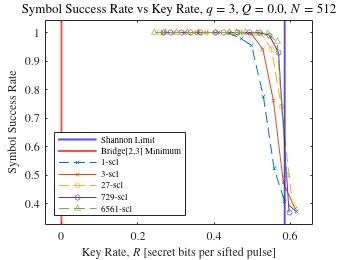

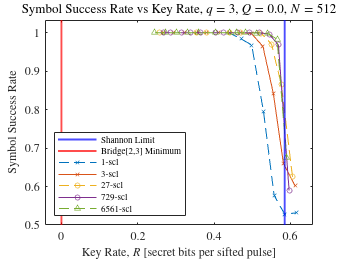

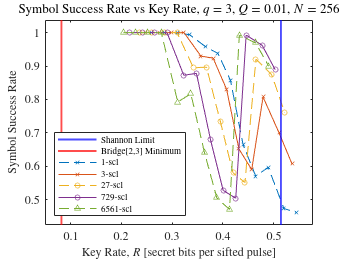

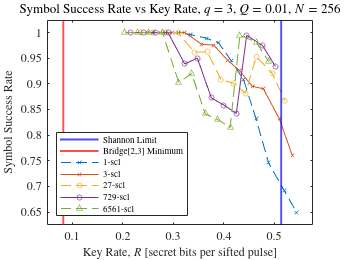

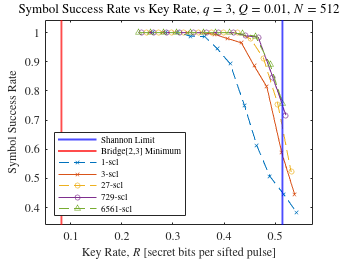

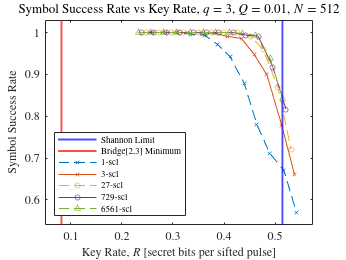

Index exceeds the number of array elements. Index must not exceed 0.

Error in get_unique (line 6)
    v = V(1);

Error in plot_ir (line 4)
    q = get_unique(A.q);

% Polar:
% Success rate vs Key rate for q=3, Q=[0.0,0.01,0.05], N=[128, 512, 4096]
show_title = true;
y_logscale = false;
agg = false;
show_sd = false;
show_legend = true;
save = true;
custom_file_name = 'polar-single';

code_strategy = 'polar';
result_type = 'full_reduce';
q_list = [3, 5];
p_err_str_list = ["0.0", "0.01", "0.05"];
N_list = [256, 512];
scl_list_size = [1, 3, 27, 729, 6561];
min_key_rate = 0.25;

for q = q_list
    for p_err_str = p_err_str_list
        for N = N_list
            A = get_data(code_strategy, q, p_err_str, agg, result_type, N, min_key_rate);
            A = filter_polar(A, scl_list_size, [], []);
            % plot_ir(A, 'success_rate_vs_key_rate', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
            plot_ir(A, 'symbol_success_rate_vs_key_rate', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
            plot_ir(A, 'alt_symbol_success_rate_vs_key_rate', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
        end
    end
end

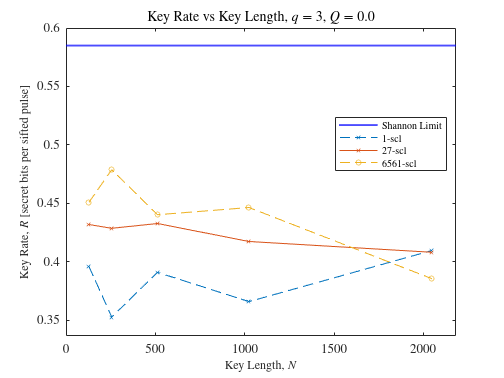

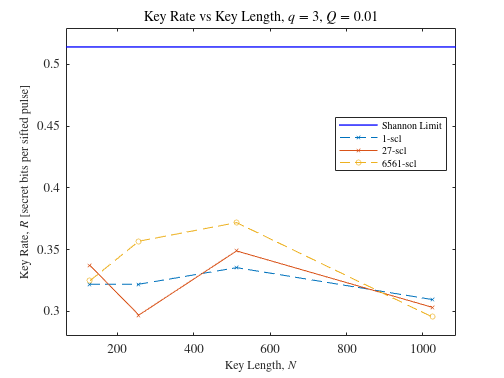

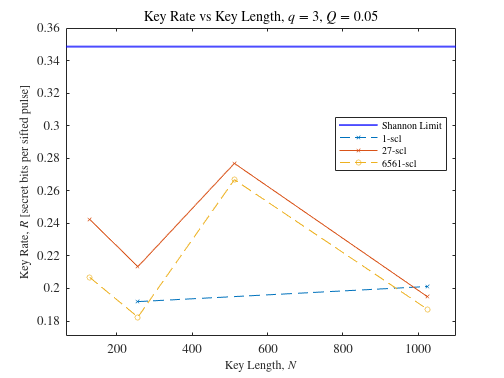

% Polar:
% Key rate vs N for q=3, Q=[0.0,0.01,0.05], alpha = 0.9
show_title = true;
y_logscale = false;
agg = false;
show_sd = false;
show_legend = true;
save = true;
custom_file_name = 'polar-single';

code_strategy = 'polar';
result_type = 'full_reduce';
q = 3;
p_err_str_list = ["0.0", "0.01", "0.05"];
success_rate_str = "0.9";
scl_list_size = [1, 27, 6561];

for p_err_str = p_err_str_list
    A = get_data(code_strategy, q, p_err_str, agg, result_type, [], []);
    A = filter_polar(A, scl_list_size, success_rate_str, []);
    plot_ir(A, 'key_rate_vs_N', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
end

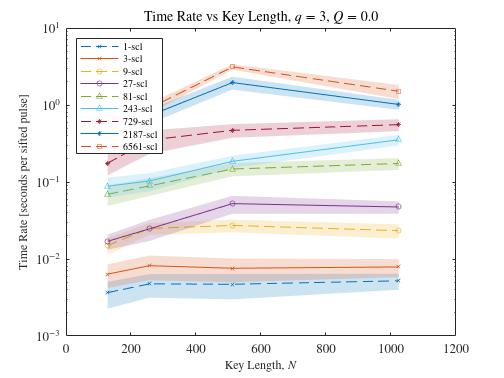

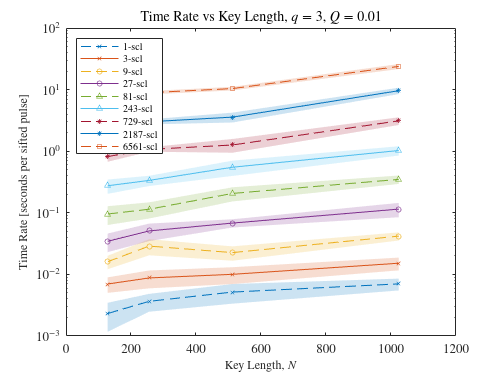

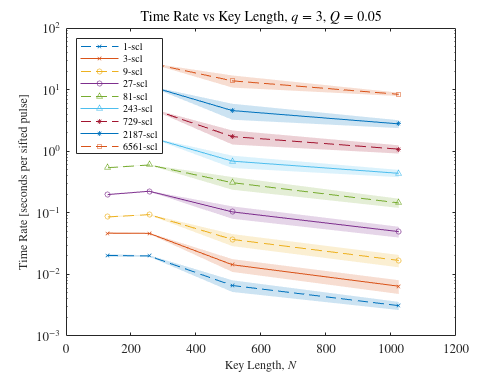

% Polar:
% Time rate vs N for q=3, Q=[0.0,0.01,0.05], relative rate 0.8
show_title = true;
y_logscale = true;
agg = false;
show_sd = true;
show_legend = true;
save = true;
custom_file_name = 'polar-single';

code_strategy = 'polar';
result_type = 'full_reduce';
q = 3;
p_err_str_list = ["0.0", "0.01", "0.05"];
relative_gap_rate = 0.8;
scl_list_size = [];

for p_err_str = p_err_str_list
    A = get_data(code_strategy, q, p_err_str, agg, result_type, [], []);
    A = filter_polar(A, scl_list_size, [], relative_gap_rate);
    plot_ir(A, 'time_rate_vs_N', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
    % plot_ir(A, 'cpu_time_rate_vs_N', show_title, y_logscale, show_sd, show_legend, save, custom_file_name);
end

% --------------------------

% Liran plot with MB and SCL for N=512, alpha=0.99

% Get MB data
agg = false;
q = 3;
p_err_str_list = ["0.0", "0.0001", "0.001", "0.01", "0.02", "0.05"];
N = 512;
success_rate_str = "0.99";
% MB params
block_length = [11];
list_size = [243];
max_num_indices_to_encode = [4];
% Polar params
scl_l = [2187];

first_iteration = true;
for p_err_str = p_err_str_list
    cur_A_mb = get_data('mb', q, p_err_str, agg, 'full_reduce', N, []);
    if strcmp(p_err_str, '0.0')
        cur_A_mb = filter_mb(cur_A_mb, block_length, list_size, max_num_indices_to_encode, []);
    else
        cur_A_mb = filter_mb(cur_A_mb, block_length, list_size, max_num_indices_to_encode, success_rate_str);
    end
    cur_A_polar = get_data('polar', q, p_err_str, agg, 'full_reduce', N, []);
    cur_A_polar = filter_polar(cur_A_polar, scl_l, success_rate_str, []);
    if first_iteration
        A_mb = cur_A_mb;
        A_polar = cur_A_polar;
        first_iteration = false;
    else
        A_mb = union(A_mb, cur_A_mb);
        A_polar = union(A_polar, cur_A_polar);
    end
end

save = true;

H_Bridge = @(x,d) -x.*log2(x) - ((1-x)).*log2((1-x)./d);
p2lambda = @(p,d) p.*(d-1)./d;
p_sift = @(p,d) (((d-1)/d).*p + d-1)./(d+1);

load('Bridge2D.mat')
prot = Bridge2D;
D = 2;
q = prot.q;
error = prot.error;
sift_vec = prot.sift_vec;
qd = prot.qd;
qB = prot.qB;
dps = prot.dps;
x = q;
f = figure;
f.Units = 'inches';
f.Position(3:4) = 1.2*[4.5 2.4];
hold on

plot(x,(qd)./ sift_vec - H_Bridge(q,D) ,'r-','LineWidth',1.5, 'DisplayName', 'Maximal $R_{QKD}^*$')

plot(x,qd ./ sift_vec,'k-.','LineWidth',1.5, 'DisplayName', '$H(A|E)$')

plot(x,H_Bridge(q,D),'b:','LineWidth',1.5, 'DisplayName', '$H(A|B)$')

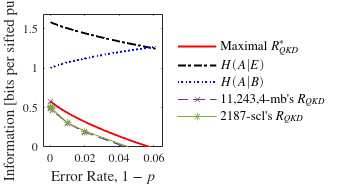

% MB plot
A_mb_stats = grpstats(A_mb, ["group_name", "p_err", "max_qkd_leak"], "mean", "DataVars", "key_rate_success_only");
plot(A_mb_stats.p_err, A_mb_stats.mean_key_rate_success_only - log2(3) + A_mb_stats.max_qkd_leak, '--x', 'DisplayName', strcat(A_mb_stats.group_name(1), "'s $R_{QKD}$"));
% plot_mean_and_shaded_sd(1-A_mb.p_err, A_mb.key_rate_success_only, A_mb.group_name);
% SCL plot
A_polar_stats = grpstats(A_polar, ["group_name", "p_err", "max_qkd_leak"], "mean", "DataVars", "key_rate_success_only");
plot(A_polar_stats.p_err, A_polar_stats.mean_key_rate_success_only - log2(3) + A_polar_stats.max_qkd_leak, '-*', 'DisplayName', strcat(A_polar_stats.group_name(1), "'s $R_{QKD}$"));
% plot_mean_and_shaded_sd(1-A_polar.p_err, A_polar.key_rate_success_only, A_polar.group_name);

axis padded

ylim([0 log2(D+1)+0.1])
% xlim([0 0.06])
xlabel("Error Rate, $1-p$",'Interpreter','latex','FontSize', 12) 
ylabel("Information [bits per sifted pulse]",'Interpreter','latex','FontSize', 12)  
box on
legend('boxoff')
legend('Location','eastoutside','Interpreter','latex','FontSize', 10)
f.CurrentAxes.TickLabelInterpreter = 'latex';

if save
    saveas(f,'/cs/usr/benjilieber/PycharmProjects/qsc_ir/results/matlab/plots/Bridge_2,MB,SCL.svg');
    saveas(f,'/cs/usr/benjilieber/PycharmProjects/qsc_ir/results/matlab/plots/Bridge_2,MB,SCL.png');
end

% Get MB data
agg = false;
q = 3;
p_err_str_list = ["0.0", "0.0001", "0.001", "0.01", "0.02", "0.05"];
success_rate_str = "0.99";
% MB params
block_length = [11];
list_size = [243];
max_num_indices_to_encode = [4];
% Polar params
scl_l = [2187];

first_iteration = true;
for p_err_str = p_err_str_list
    cur_A_mb = get_data('mb', q, p_err_str, agg, 'full_reduce', [], []);
    if strcmp(p_err_str, '0.0')
        cur_A_mb = filter_mb(cur_A_mb, block_length, list_size, max_num_indices_to_encode, []);
    else
        cur_A_mb = filter_mb(cur_A_mb, block_length, list_size, max_num_indices_to_encode, success_rate_str);
    end
    cur_A_polar = get_data('polar', q, p_err_str, agg, 'full_reduce', [], []);
    cur_A_polar = filter_polar(cur_A_polar, scl_l, success_rate_str, []);
    if first_iteration
        A_mb = cur_A_mb;
        A_polar = cur_A_polar;
        first_iteration = false;
    else
        A_mb = union(A_mb, cur_A_mb);
        A_polar = union(A_polar, cur_A_polar);
    end
end

% Table of key rates for all (N, Q) with alpha=0.99
mb_max_N_2 = min(grpstats(A_mb, ["group_name", "p_err_str"], "max", "DataVars", "N_2").max_N_2);
polar_max_N_2 = min(grpstats(A_polar, ["group_name", "p_err_str"], "max", "DataVars", "N_2").max_N_2);
max_N_2 = min(mb_max_N_2, polar_max_N_2);
tol = 5 * eps(100); % A very small value
A_mb = A_mb(A_mb.N_2 <= max_N_2 + tol, :);
A_polar = A_polar(A_polar.N_2 <= max_N_2 + tol, :);

A_mb_stats = grpstats(A_mb, ["p_err_str", "N_2", "theoretic_key_rate", "max_qkd_leak"], "mean", "DataVars", "key_rate_success_only");
A_polar_stats = grpstats(A_polar, ["p_err_str", "N_2", "theoretic_key_rate", "max_qkd_leak"], "mean", "DataVars", "key_rate_success_only");

A = table();
A.p_err(:, 1) = double(A_mb_stats.p_err_str(:));
A.N(:, 1) = A_mb_stats.N_2(:);
A.max_key_rate(:, 1) = A_mb_stats.theoretic_key_rate(:, 1) + A_mb_stats.max_qkd_leak(:, 1) - log2(3);
A.mb_key_rate(:, 1) = A_mb_stats.mean_key_rate_success_only(:, 1) + A_mb_stats.max_qkd_leak(:, 1) - log2(3);
A.polar_key_rate(:, 1) = A_polar_stats.mean_key_rate_success_only(:, 1) + A_mb_stats.max_qkd_leak(:, 1) - log2(3);

% latex_table = latexTable(A)
% latex_table = latex(sym(A.N(:)))
table2latex(A, '/cs/usr/benjilieber/PycharmProjects/qsc_ir/results/matlab/plots/latex_table')

filename = '/cs/usr/benjilieber/PycharmProjects/qsc_ir/results/matlab/plots/latex_table.tex'